syms s
syms wg real positive
%Función de transferencia en simbolico, Cambiarla a la requerida
num = [156.4]

num = 156.4000

den = [1 1.7 71.93]

den =     1.0000    1.7000   71.9300



FmReq=60;

nums = writePolinomio(num,0);
dens = writePolinomio(den,0);
Gs = nums/dens

$$Gs = \frac{782}{5\,\left(s^{2}+\frac{17\,s}{10}+\frac{7193}{100}\right)}$$


kp = 5

kp = 5

ki = 10

ki = 10

kd = 1

kd = 1

N=100;
Cs = kp+ki/s+kd*(N/(1+N*(1/s)))

$$Cs = \frac{10}{s}+\frac{100}{\frac{100}{s}+1}+5$$


s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



G = writePolinomio(num,1)/writePolinomio(den,1)

G =
 
         156.4
  -------------------
  s^2 + 1.7 s + 71.93
 
Continuous-time transfer function.




C = kp+ki/s+kd*(N/(1+N*(1/s)))

C =
 
  105 s^2 + 510 s + 1000
  ----------------------
       s^2 + 100 s
 
Continuous-time transfer function.




[Gm Pm Wcg Wcp] = margin(C*G)

Gm = Inf

Pm = 40.4574

Wcg = Inf

Wcp = 110.7253


theta = 30;
Thetam = FmReq - Pm + theta

Thetam = 49.5426


b=(1+sind(Thetam))/(1-sind(Thetam))

b = 7.3643


syms s
wg = double(vpa(solve(20*log10(abs(subs(Cs*Gs,s,1i*wg)))==-10*log10(b),wg)))

wg = 199.8130


T2 = 1/(sqrt(b)*wg(1))

T2 = 0.0018


s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



C2 = (1+b*T2*s)/(1+T2*s)

C2 =
 
  0.01358 s + 1
  --------------
  0.001844 s + 1
 
Continuous-time transfer function.



Gl = C*C2*G

Gl =
 
        223 s^3 + 1.751e04 s^2 + 8.189e04 s + 156400
  ---------------------------------------------------------
  0.001844 s^5 + 1.188 s^4 + 102.1 s^3 + 255.2 s^2 + 7193 s
 
Continuous-time transfer function.



Go = feedback(Gl,1)

Go =
 
                223 s^3 + 1.751e04 s^2 + 8.189e04 s + 156400
  -------------------------------------------------------------------------
  0.001844 s^5 + 1.188 s^4 + 325.2 s^3 + 1.776e04 s^2 + 8.908e04 s + 156400
 
Continuous-time transfer function.



C2D = c2d(C2,1E-03,'least-squares')

C2D =
 
  5.918 z - 5.476
  ---------------
    z - 0.5567
 
Sample time: 0.001 seconds
Discrete-time transfer function.




RedNum = cell2mat(C2D.Numerator)

RedNum =     5.9180   -5.4763


RedDen = cell2mat(C2D.Denominator)

RedDen =     1.0000   -0.5567



polos=pole(Go)

polos = 1.0e+02 *

  -2.8736 + 2.3155i
  -2.8736 - 2.3155i
  -0.6386 + 0.0000i
  -0.0268 + 0.0160i
  -0.0268 - 0.0160i


ceros=zero(Go)

ceros =  -73.6306 + 0.0000i
  -2.4286 + 1.9042i
  -2.4286 - 1.9042i



[Gm Pm Wcg Wcp] = margin(Gl)

Gm = Inf

Pm = 75.2277

Wcg = Inf

Wcp = 199.7845

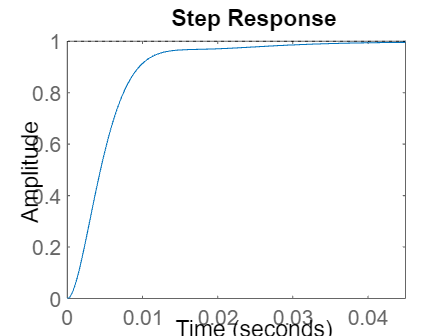

step(Go)

stepinfo(Go)

ans = struct with fields:
         RiseTime: 0.0081
    TransientTime: 0.0262
     SettlingTime: 0.0262
      SettlingMin: 0.9024
      SettlingMax: 0.9963
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9963
         PeakTime: 0.0510


% figure()
% yline(-3,'--')
% hold on
% margin(Gl)
% grid on


syms s
syms wC real positive
C2s = vpa((1+b*T2*s)/(1+T2*s))

$$C2s = \frac{0.013581316342375004610487643219585\,s+1.0}{0.0018442117863747486353892535149157\,s+1.0}$$

wCorte = double(vpa(solve(20*log10(abs(subs(Cs*Gs*C2s,s,1i*wC)))==-3,wC)))

wCorte = 273.8061